# `Data Pre-processing`

`After import signals from outside. The raw signal can not be used directly, this step is required to process the signal into the from that can be used in Convolutional Neural Network.`

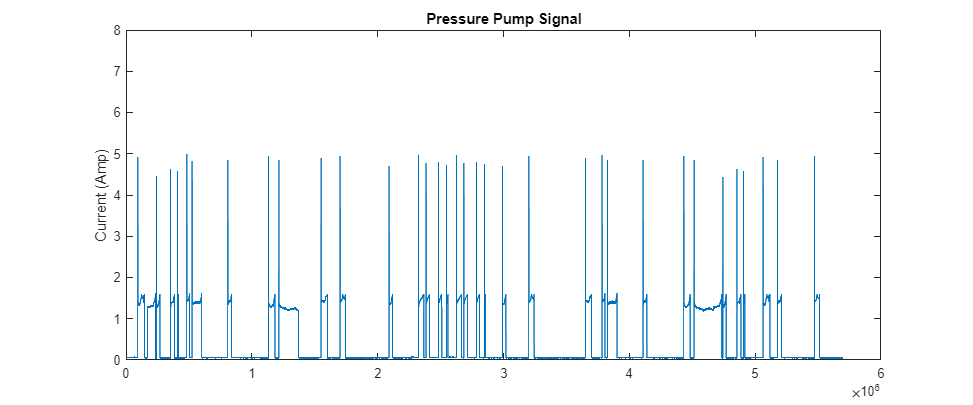

% Load Data from folder into workspace
load normal0000.mat normal3hrs
load abnormal0000.mat abnormal0000
current = normal3hrs;
f1 = figure;
f1.Position(3:4) = [1200, 500];
figure(f1);
plot(current);
title("Pressure Pump Signal")
ylabel("Current (Amp)");
ylim([0, 8]);

% Data Visualization
start = 1;
step = 300000;
overlap = 0.5;
for index = 1:5
    stop = start+(step)-1;
    if stop > length(current)
        break;
    end
    amp = current(start:stop);
    f2 = figure;
    f2.Position(3:4) = [1500, 600];
    figure(f2);
    plot(amp,"Color",rand(1,3));
    title("Plot "+ index)
    ylabel("Current (Amp)");
    ylim([0, 8]);
    fprintf("%d:%d", start, start+(step)-1);
    start = (start + (step*overlap));
end

% Cut a large signal into several small signals. Let a small signal be 10
% minutes per each and save them as csv file 300000 rows.

start = 1;                      % start time
step = 300000;                  % window sized 10 minute
overlap = 0.2;                  % overlap 80%

for index = 1:length(current)/(step*overlap) - 1
    % set stop index
    stop = start+(step)-1;
    % check if index exceeds range. if index out of range, the loop will stop.
    if stop > length(current)
        break;
    end
    % Declare a buffer to store the cutted data.
    amp = current(start:stop);
    % name the file.
    filename = ['G:\Document_G\PUMP\Dataset_normal\dataset' num2str(index) '.csv'];
    % save file to folder
    writematrix(amp, filename);
    % slide the window for any overlapping
    start = (start + (step*overlap)); 
end

% Create Matrix to stores all the dataset (csv files from previous step),The numbers of column is the numbers
% of dataset in folder.

files = dir("G:\Document_G\PUMP\Dataset_normal\*.csv");
% Create zero matrix with dimension row of a csv file and column of numbers of files
figmatrix = zeros(step, length(files));
for i = 1:length(files)
    column = readmatrix(['G:\Document_G\PUMP\Dataset_normal\dataset' num2str(i) '.csv']);
    figmatrix(:, i) = column(1:step);
end

% Create Time-Frequency Representations (spectrogram) uses stft function and save them in folder.
for num = 1:length(files)
    fs = 500;
    L = length(figmatrix(:,num));
    fig = figure('visible','off');
    stft(figmatrix(:,num), fs, Window=hamming(3500,"periodic"), OverlapLength=2800, FFTLength=L, FrequencyRange="centered");
    ylim([-2,2]);
    saveas(fig, fullfile("G:\Document_G\PUMP\fig_normal", ['myPlot' num2str(num) '.jpeg']));
    clear fs L fig
end

% resize the spectrogram to 224x224x3 double image to be compatible with GoogleNet

file = dir("G:\Document_G\PUMP\fig_normal\*.jpeg");

parfor i = 1:length(file)
    f = fullfile("G:\Document_G\PUMP\fig_normal", file(i).name);
    im = im2double(imread(f));
    imwrite(imresize(im,[224 224]),fullfile("G:\Document_G\PUMP\Label_data\Normal", ['Normal' num2str(i) '.jpg']));
end